y = [1 5 NaN 4];
z = [1 2 Inf 4 5];



%Detecta y elimina los datos NaN
y(isnan(y)) = [];  
y(isnan(z)) = [];  


%Detecta y elimina los datos inf
y(isinf(y)) = []; % Reemplaza Inf por 'valor_especifico'
z(isinf(z)) = [];  % Reemplaza Inf por 'valor_especifico'

% Revision del tamaño de los vectores, deben ser iguales para operarlos
if length(y) == length(z)
    disp('Los vectores tienen el mismo tamaño.');
else
    disp('Los vectores tienen tamaños diferentes, se agregarán 0 al vector faltante.');
end

Los vectores tienen tamaños diferentes, se agregarán 0 al vector faltante.



%Revisar si los vectores son del mismo tamaño. Rellena el vector con ceros
%al final
max_length = max(length(y), length(z));
y(end+1:max_length) = 0;
z(end+1:max_length) = 0;

% Definir 
Ly=length(y);
n = 0:Ly-1;

%Normalizar una señal
senalNormalizada = normalize(y, 'range', [0, 1]);


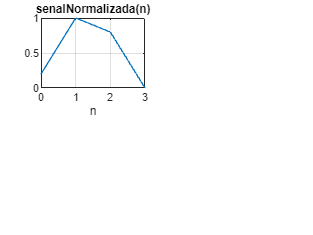

subplot(2,2,1); plot(n,senalNormalizada);title('senalNormalizada(n)' ); xlabel('n');grid on;